**Creat a satellite scenario**

Create the scenario using the satelliteScenario() command and initialization parameters:

startTime = datetime(2022,10,1,12,30,0);
stopTime = startTime + days(7);
sampleTime = 60;
sc = satelliteScenario(startTime,stopTime,sampleTime);

**Add satellites to the scenario**

sat1 = satellite(sc, "ECE5695-Project-1\orbitalData\TLE\AEHF1-TLE-Data.tle");
sat2 = satellite(sc, "ECE5695-Project-1\orbitalData\TLE\AEHF2-TLE-Data.tle");
sat3 = satellite(sc, "ECE5695-Project-1\orbitalData\TLE\AEHF3-TLE-Data.tle");
sat4 = satellite(sc, "ECE5695-Project-1\orbitalData\TLE\AEHF4-TLE-Data.tle");
sat5 = satellite(sc, "ECE5695-Project-1\orbitalData\TLE\AEHF5-TLE-Data.tle");
sat6 = satellite(sc, "ECE5695-Project-1\orbitalData\TLE\AEHF6-TLE-Data.tle");
sats = [sat1 sat2 sat3 sat4 sat5 sat6];

**Add cameras to the scenario**

Use the conicalSensor() command to add camera sensors to the scenario:

for idx = 1:numel(sats)
    name = sats(idx).Name + " Camera";
    conicalSensor(sats(idx), "Name", name, "MaxViewAngle", 90);
end

% Retrieve the cameras
cam = [sats.ConicalSensors];

**Define groundstation(s) for scenario**

name = "UCCS Campus";
lat = 38.8886569787;
lon = -104.793021161;
gs = groundStation(sc,"Name",name,"Latitude",lat, ...
    "Longitude", lon);

**Add access analysis between cameras and groundstation**

for idx = 1:numel(cam)
    access(cam(idx), gs)
end

ans =   Access with properties:
    Sequence:  [7 13]
    LineWidth:  3
    LineColor:  [0.3922 0.8314 0.0745]

ans =   Access with properties:
    Sequence:  [8 13]
    LineWidth:  3
    LineColor:  [0.3922 0.8314 0.0745]

ans =   Access with properties:
    Sequence:  [9 13]
    LineWidth:  3
    LineColor:  [0.3922 0.8314 0.0745]

ans =   Access with properties:
    Sequence:  [10 13]
    LineWidth:  3
    LineColor:  [0.3922 0.8314 0.0745]

ans =   Access with properties:
    Sequence:  [11 13]
    LineWidth:  3
    LineColor:  [0.3922 0.8314 0.0745]

ans =   Access with properties:
    Sequence:  [12 13]
    LineWidth:  3
    LineColor:  [0.3922 0.8314 0.0745]


% Retrieve the access analysis objects
ac = [cam.Accesses];

% Properties of access analysis objects
ac(1)

ans =   Access with properties:
    Sequence:  [7 13]
    LineWidth:  3
    LineColor:  [0.3922 0.8314 0.0745]

**Create scenario viewer (brings up viewer)**

v = satelliteScenarioViewer(sc);

**Visualize the Field of View of the Camera**

%fov = fieldOfView(cam([cam.Name] == "sat 4 Camera"))
fov1 = fieldOfView(cam(1), "LineColor", 'r');
fov2 = fieldOfView(cam(2), "LineColor", 'g');
fov3 = fieldOfView(cam(3), "LineColor", 'b');
fov4 = fieldOfView(cam(4), "LineColor", 'c');
fov5 = fieldOfView(cam(5), "LineColor", 'm');
fov6 = fieldOfView(cam(6), "LineColor", 'y');

**Customize the Visualization**

Use hide to hide the satellite orbits and declutter the visualization

hide([sats.Orbit])

Change the color of access visualizations to green

for idx = 1:numel(ac)
    ac(idx).LineColor = 'green';
end

**Define times the cameras can photograph the groundstation**

Use accessIntervals to determine the times when there is access between each camera and UCCS groundstation

accessIntervals(ac)

ans = 3×8 table
        Source           Target        IntervalNumber         StartTime                EndTime           Duration     StartOrbit    EndOrbit
    ______________    _____________    ______________    ____________________    ____________________    _________    __________    ________
    "38254 Camera"    "UCCS Campus"          1           01-Oct-2022 12:30:00    08-Oct-2022 12:30:00    6.048e+05        1            8    
    "39256 Camera"    "UCCS Campus"          1           01-Oct-2022 12:30:00    08-Oct-2022 12:30:00    6.048e+05        1            8    
    "43651 Camera"    "UCCS Campus"          1           01-Oct-2022 12:30:00    08-Oct-2022 12:30:00    6.048e+05        1            8    

**Show the visualization**

play(sc);

**Calculate system-wide access percentage**

In addition to determining the times when each camera can photograph UCCS, it is also required to determine the system-wide access percentage, which is the percentage of time from the scenario start time to stop time when at least one satellite can photograph UCCS.

for idx = 1:numel(ac)
    [s, time] = accessStatus(ac(idx));

    if idx == 1
        % Initialize system-wide access status vector in first iteration
        systemWideAccessStatus = s;
    else
        systemWideAccessStatus = or(systemWideAccessStatus, s);
    end
end

**Plot the system-wide access status with respect to time**

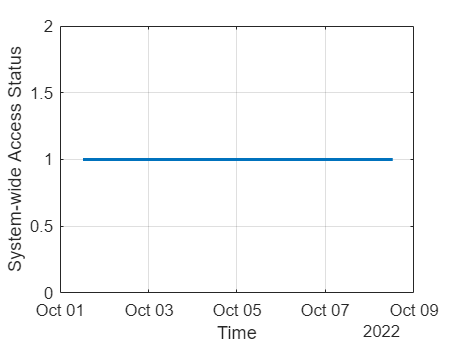

plot(time, systemWideAccessStatus, "LineWidth", 2);
grid on;
xlabel("Time");
ylabel("System-wide Access Status")

Whenever system-wide access status is 1 (True), at least one camera can photograph UCCS

**Determine which satellite can view the ground station**

Use the nnz function

n = nnz(systemWideAccessStatus)

n = 10081

Determine the total time when at least one camera can photograph UCCS. This is accomplished by multiplying the number of True elements by the scenario's sample time

systemWideAccessDuration = n*sc.SampleTime % seconds

systemWideAccessDuration = 604860

Use seconds to calculate the total scenario duration

scenarioDuration = seconds(sc.StopTime - sc.StartTime)

scenarioDuration = 604800

Calculate the system-wide access percentage

systemWideAccessPercentage = (systemWideAccessDuration/scenarioDuration)*100

systemWideAccessPercentage = 100.0099

**Improve system-wide access percentage by making cameras track UCCS**

The default attitude configuration of the satellites is such that their yaw axes point straight down towards nadir (the point on Earth directly below the satellite)

If instead the cameras always point at UCCS, the latter is always inside the cameras field of view as long as the Earth is not blocking the line of sight

for idx = 1:numel(sats)
    pointAt(sats(idx), gs)
end

for idx = 1:numel(ac)
    [s, time] = accessStatus(ac(idx));

    if idx == 1
        % Initialize system-wide access status vector in first iteration
        systemWideAccessStatus = s;
    else
        systemWideAccessStatus = or(systemWideAccessStatus, s);
    end
end

n = nnz(systemWideAccessStatus);
systemWideAccessDuration = n*sc.SampleTime;
systemWideAccessPertageWithTracking = (systemWideAccessDuration/scenarioDuration)*100

systemWideAccessPertageWithTracking = 100.0099

The system-wide access % has improved. This is the result of the  cameras continuously pointing at UCCS. This can be visualized by using the play command

play(sc)

Notice the field of view contour is no longer circular. This is because the camera is not pointing straight down anymore as it is tracking UCCS